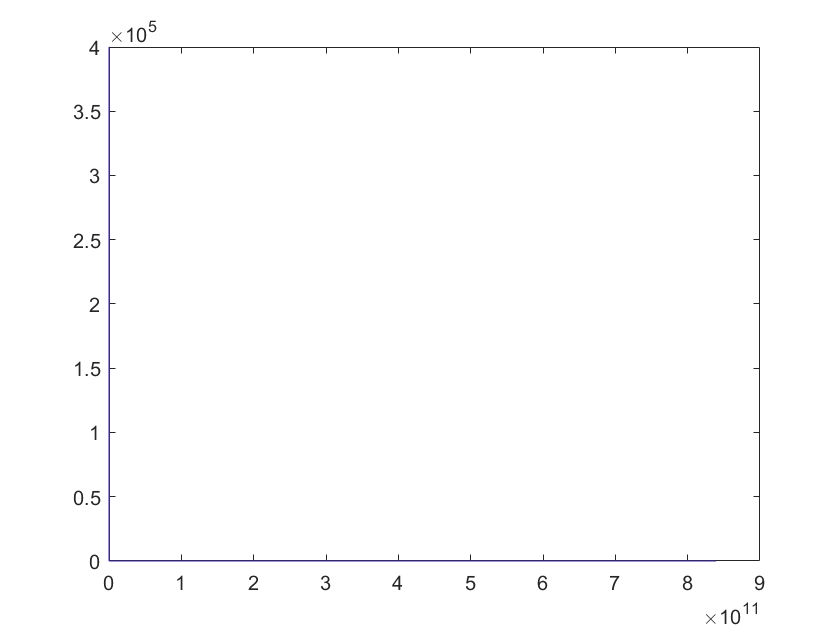

% 第五章第23题的检验
cpc = 800000;

samp = normrnd(0, 1, 1, cpc);
to_test = set_dist(samp, cpc);

figure(1);
hist(to_test, 1600);

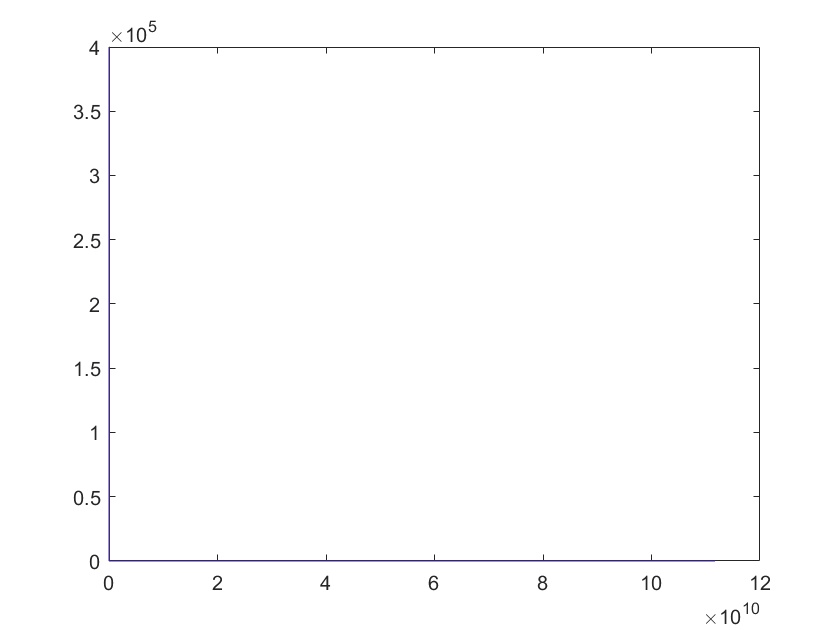


f_sam = frnd(1, 1, 1, cpc / 2);

figure(2);
hist(f_sam, 1600);

function out = set_dist(rnds, capa)
    out = zeros(1, capa / 2);
    for i = 1:2:capa
        % (x1 + x2)/(x1 - x2) squared
        out((i + 1)/2) = ((rnds(i) + rnds(i+1)) / (rnds(i) - rnds(i+1))) ^2;
    end
end